# Part 2: Load and clean data

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

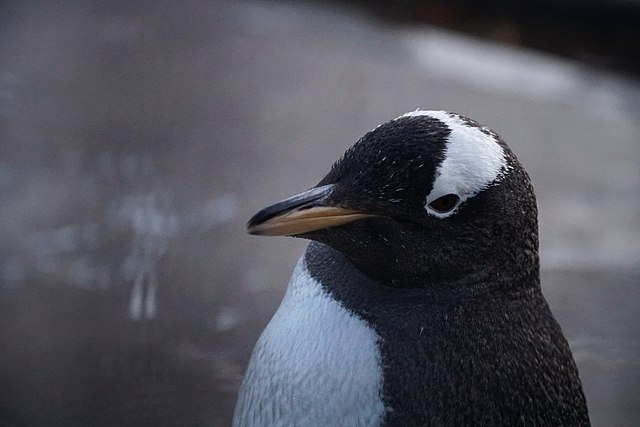

A Gentoo [penguin](https://commons.wikimedia.org/wiki/File:Gentoo_penguin_in_Edinburgh_Zoo_04.jpg), perhaps contemplating life. 

## 1:  Load data 

To read more about loading data, go back to the Biosciences Data Module***(add link to module 1 Github)***. A quick summary of how to grab the correct data for this module follows: 

Step 1: [Click me](https://github.com/mwaskom/seaborn-data/blob/master/penguins.csv)

Step 2: Now you're looking at a GitHub repository that contains this data as a table. On this page, click the **Download raw file **button**. '**penguins.csv' will be saved to your Downloads folder.

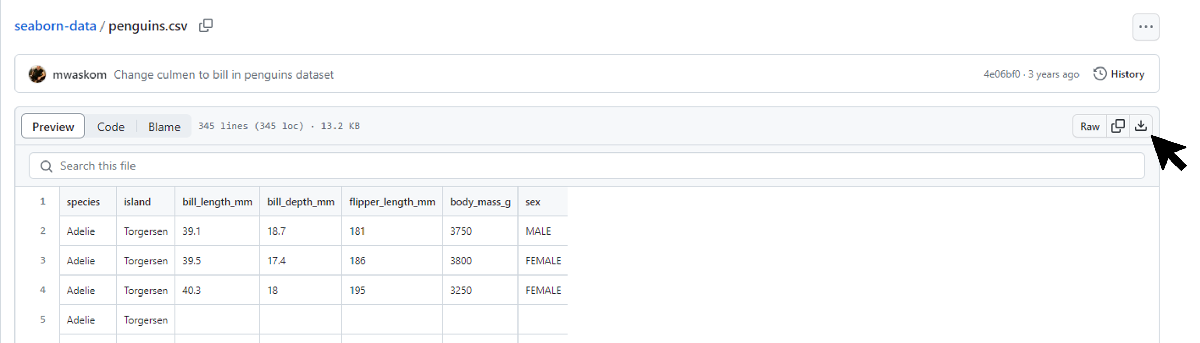

Step 3: Copy and paste this file into the folder these live scripts are saved in: 

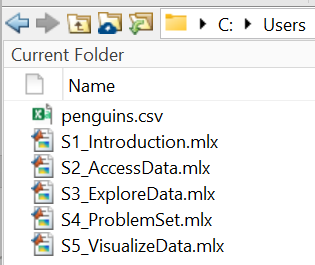

Because this data is in a repository, we can also pull the data directly into MATLAB® from Git. 

Copy and paste 'penguins.csv' to the folder this live script is in and run the cell below. Even if you downloaded the data in Module 1***(add link to module 1 Github)***, you'll need to copy and paste that file here, or [add it to your MATLAB path](https://www.mathworks.com/help/matlab/ref/addpath.html). 

filename = "penguins.csv";
penguins = readtable(filename);

As described in the biosciences data module,***(add link to module 1 Github)*** we'll make the variables into categorical arrays for ease of use:

penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);

## 2:  Clean data 

In the biosciences data module, we noted that some data values were missing ([NaN](https://www.mathworks.com/help/matlab/matlab_prog/infinity-and-nan.html)). These will prove problematic when we try to apply statistical methods to the data, so it's best to remove those values from the dataset here. 

When we are talking about statistical methods for describing data, we are talking about using a collected sample of an overall population to make descriptions of the population as a whole. For example, our data set represents 124 Gentoo penguins, which is of course not the totality of Gentoo penguins in Antarctica. It varies based on the field and the question, but there is always a minimum number of data points you would need to make a meaningful biological observation. In our case, we have plenty of data and if we clean the dataset and lose a couple of penguins we will still be okay. That being said, it's good to keep in mind that if your data set is very small or you have a lot of missing values, you may not have enough data to make meaningful observations. And in that case, you'll probably need to collect more data!

Okay, let's clean this data up a bit: 

### Method 1: Use an app to do the cleaning 

1: Go to the **Apps** Tab and in the **MATLAB** section select   **Data Cleaner.** If you're having trouble locating it in the sea of apps, you can always search through the apps pane.

2: In the** Data Cleaner** window, select 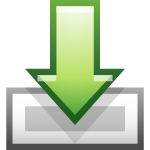 **Import**,** Import from Workspace**, and select `penguins`.

Go to the **Data** tab and take a peek at the data. You'll see the data itself as well as statistical information about each column (mean, standard deviation, etc. - but more on this later!) You'll see how many values are missing. In our case, it looks like there are two penguins for which bill length, depth, flipper length, and body mass are missing. There are more penguins that are missing information about their sex. Let's remove all of these penguins. 

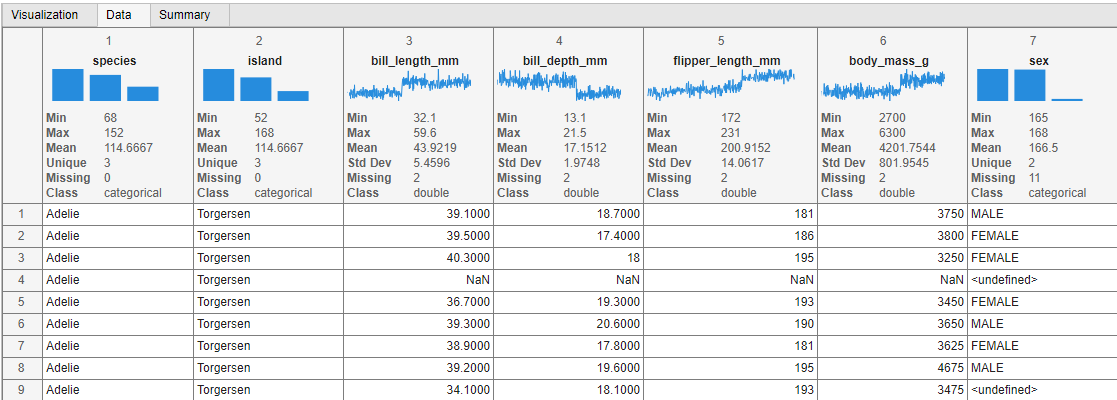

3- Click **Clean Missing Data** and the cleaning window will pop up on the right. 

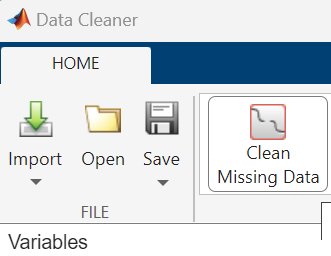

4- Let's select which variables we want to clean. Go to the **Table variables** and click the three dots. In this case, let's broadly remove any missing data, so **Select All **to select all the variables. Under cleaning method, select **Remove Missing** and then **Accept**. 

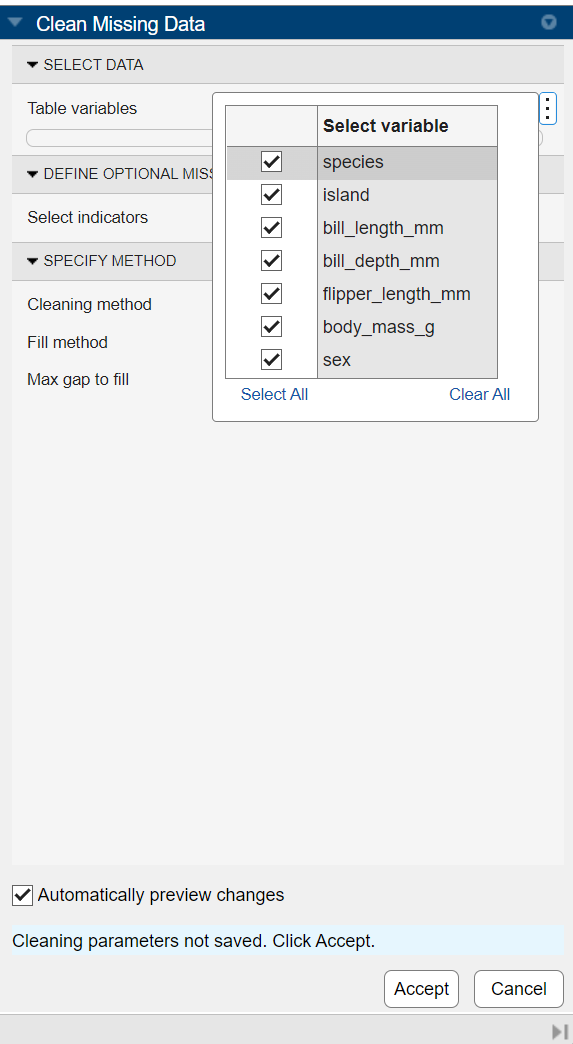

5- Export the new, cleaned-up version of the table. Click 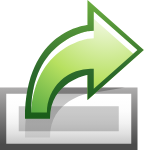**Export** at the top of the cleaning window and **Export to Workspace**. A window will pop up and tell you your table is being exported to your MATLAB workspace with a new name, and this is the table you will work with for the rest of this module. Make sure your cleaned table is named `penguins1.`

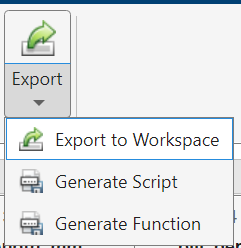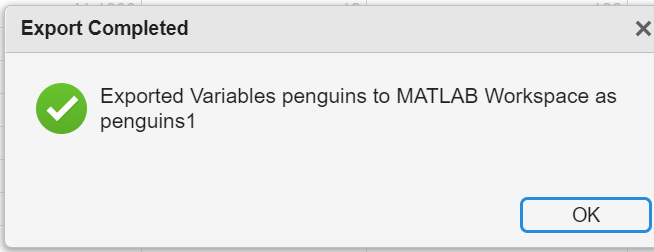

Once your table is exported, you can close the **Data Cleaner** app.

  Check out `penguins1`. How many penguins did we lose in cleaning this data? (***Hint:*** try utilizing `size(penguins)` and `size(penguins1)`). 

### Method 2: DIY

We can also write a MATLAB command (use the function [`rmmissing()`](https://www.mathworks.com/help/matlab/ref/rmmissing.html)) to clean our data. 

   Type the following into the code block below to remove missing data from `penguins` and save it to a variable called `penguins1`: 

Now that we no longer have penguins with missing data in our dataset, let's explore the data further. 

[*Continue to next section (Exploring data)*](matlab: edit S3_Exploring_data.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)